n_min_start =     27


n_max_start =    335


T_buscado =      7.575757575757576e-06


ans =   -1.151515151515043


cant1514 =    740


ans =   -0.151515151515053


cant1515 =         7468


ans =    0.848484848484938


cant1516 =         2032


presicion =      3.962168339321002e-11


media =      1.173283202148437e-09


T_buscado =      7.575757575757576e-06


Tiempo_final =      7.576173283202149e-06


error =      4.157074445732274e-10


n_min_start =     27


n_max_start =    335


T_buscado =      5.000000000000000e-06


presicion =      3.509054591965580e-11


media =      4.355931748046857e-10


T_buscado =      5.000000000000000e-06


Tiempo_final =      5.000435593174805e-06


error =      4.355931748045955e-10


ans =        10240


n_min_start =     27


n_max_start =    335


T_buscado =      1.000000000000000e-06


tiempo_muerto =      7.500000000000000e-08


ans =    185
   186
   187
   188
   189
   190
   191
   192
   193
   194


ans =        10240


h_200_malardos =   Histogram with properties:

             Data: [1100×1 double]
           Values: [1 1 0 0 0 0 0 0 1 2 0 0 4 39 6 24 21 12 0 14 21 0 0 4 0 0 8 0 6 3 11 0 2 1 0 7 46 63 52 105 18 13 31 36 41 17 74 2 0 0 21 0 0 4 1 4 1 0 0 4 0 0 13 49 31 167 24 11 1 4 10 0 38 6 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 1 14 2 4 2 0 0 0 0 0 1]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 1.170000000000007e-12
        BinLimits: [3.990000000000000e-10 5.160000000000000e-10]
    Normalization: 'count'
        FaceColor: [1 0 0]
        EdgeColor: [0 0 0]

  Show all properties


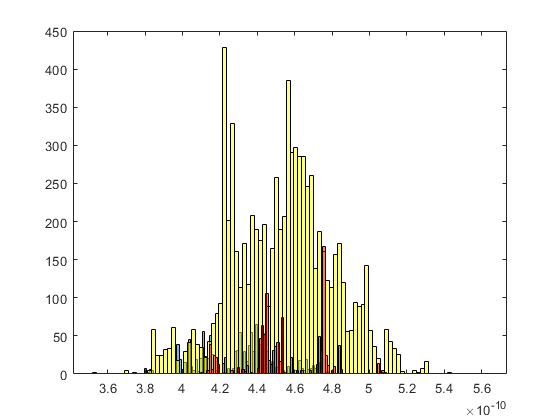

presicion =      2.714493842100236e-11


media =      4.507079453124996e-10


Tiempo_final =      1.000450707945312e-06


error =      4.507079453125434e-10


n_min_start =     27


n_max_start =    335


T_buscado =      4.081632653061224e-07


presicion =      2.981934459866805e-11


media =      3.545207416992200e-09


ans = "cantidad de coarse 80: 767"

ans = "cantidad de coarse 81: 2588"

ans = "cantidad de coarse 82: 6885"

T_buscado =      4.081632653061224e-07


Tiempo_final =      4.085452074169922e-07


error =      3.819421108697417e-10


n_min_start =     27


n_max_start =    335


T_buscado =      2.500000000000000e-07


ans = '50 coarse son: 2.500000e-07 y lo buscado es: 2.500000e-07'

presicion =      2.391556002457765e-11


media =      3.830378437500029e-10


ans =    796


ans =    822


ans =         8622


T_buscado =      2.500000000000000e-07


Tiempo_final =      2.503830378437500e-07


error =      3.830378437500190e-10


ans =        10240


n_min_start =     27


n_max_start =    335


T_buscado =      1.515151515151515e-07


tiempo_muerto =      7.500000000000000e-08


presicion =      2.673183161454074e-11


media =      1.899379689453161e-09


ans =        10240


ans =         1317


ans =         2587


error =      3.842281743016377e-10


n_min_start =     27


n_max_start =    335


T_buscado =      1.000000000000000e-07


presicion =      2.515971468062107e-11


media =      3.981071347656226e-10


ans =    963


ans =    107


ans =         9170


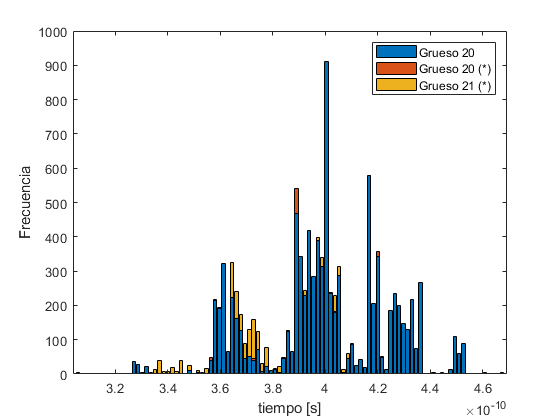

T_buscado =      1.000000000000000e-07


Tiempo_final =      1.003981071347656e-07


error =      3.981071347656210e-10


clear;
% Define the list of .mlx files to execute
mlx_files = {'data_processing_66k.mlx', ...
 'data_processing_100k.mlx', 'data_processing_500k.mlx',...
 'data_processing_1225M.mlx', 'data_processing_2M.mlx', ...
 'data_processing_3_3M.mlx', 'data_processing_5M.mlx'};  

% Initialize empty arrays to collect the variables
media_all = [];
presicion_all = [];
error_all = [];
t_buscado_all = [];
titles_all = {};
coarse_c = [];

% Loop through each file and run it
for i = 1:length(mlx_files)
    % Extract the title from the file name
    [~, name, ~] = fileparts(mlx_files{i});
    title = strrep(name, 'data_processing_', '');
    
    % Run the script
    run(mlx_files{i});
    
    % Collect the variables from each script
    coarse_c          = [coarse_c; coarse_correcto];
    t_buscado_all = [t_buscado_all; T_buscado];
    media_all = [media_all; media];
    presicion_all = [presicion_all; presicion];
    error_all = [error_all; error];
    titles_all = [titles_all; {title}];
end


% Create a table with the collected data
results_table = table(titles_all, media_all, presicion_all, error_all, t_buscado_all, coarse_c,...
    'VariableNames', {'Title', 'Media', 'Presicion', 'Error', 'T_buscado', 'Coarse'});

% Display the table
disp(results_table);

      Title             Media                 Presicion                 Error                 T_buscado          Coarse
    _________    ____________________    ____________________    ____________________    ____________________    ______

    {'66k'  }    1.17328320214844e-09      3.962168339321e-11    4.15707444573227e-10    7.57575757575758e-06     1515 
    {'100k' }    4.35593174804686e-10    3.50905459196558e-11    4.35593174804595e-10                   5e-06     1000 
    {'500k' }      4.507079453125e-10    2.71449384210024e-11    4.50707945312543e-10                   1e-06      200 
    {'1225M'}     3.5452074169922e-09    2.98193445986681e-11    3.81942110869742e-10    4.08163265306122e-07       81 
    {'2M'   }    3.83037843750003e-10    2.39155600245776e-11    3.83037843


% Save the table to a .mat file
save('results_table.mat', 'results_table');

% Optionally, save the table to a CSV file
writetable(results_table, 'results_table.csv');

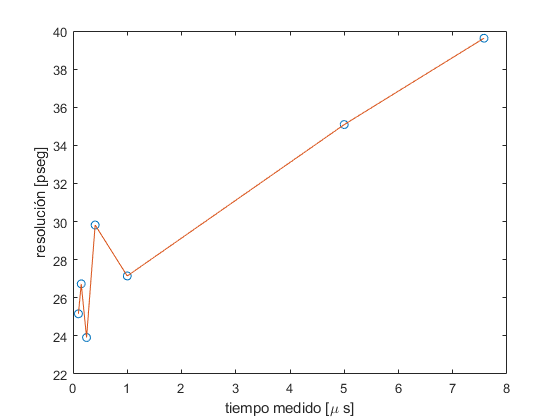

t_fino_i = zeros(7,1);
format long
for i=1:height(results_table)
    t_fino_i(i,1) = results_table.T_buscado(i) - results_table.Coarse(i)*T;
end

x = [];
y = [];
for i=1:height(results_table)
    x(i) = results_table.T_buscado(i);
    y(i) = results_table.Presicion(i);
end
plot(x/1e-6, y/1e-12, 'o', x/1e-6, y/1e-12); ylabel('resolución [pseg]'); xlabel('tiempo medido [\mu s]')